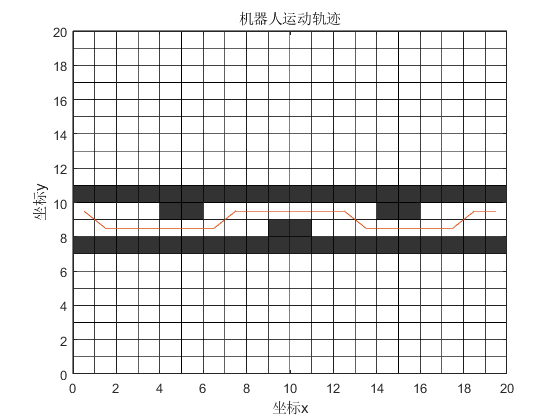

G=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1; 
   0 0 0 0 1 1 0 0 0 0 0 0 0 0 1 1 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0; 
   1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0; 
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;];
MM=size(G,1);                  	    
Tau=ones(MM*MM,MM*MM);       
Tau=8.*Tau; 
K=200;                       	   
M=200;                        	 
S=1+20*10 ;                         	  
E=20*11;                      
Alpha=1;                      	   
Beta=7;                       	  
Rho=0.3 ;                      	   
Q=1;                               
minkl=inf; 
mink=0; 
minl=0; 
D=G2D(G); 
N=size(D,1);              
 a=1;                     
 Ex=a*(mod(E,MM)-0.5);    
 if Ex==-0.5 
Ex=MM-0.5; 
end 
Ey=a*(MM+0.5-ceil(E/MM)); 
 Eta=zeros(N);            

 for i=1:N 
 ix=a*(mod(i,MM)-0.5); 
   if ix==-0.5 
   ix=MM-0.5; 
   end 
iy=a*(MM+0.5-ceil(i/MM));  
   if i~=E 
   Eta(i)=1/((ix-Ex)^2+(iy-Ey)^2)^0.5; 
   else 
   Eta(i)=100; 
   end 
end 
ROUTES=cell(K,M);     
PL=zeros(K,M);         
                      
for k=1:K 
for m=1:M 

W=S;                  
Path=S;                
PLkm=0;               
TABUkm=ones(N);       
TABUkm(S)=0;          
DD=D;                 

DW=DD(W,:); 
DW1=find(DW); 
for j=1:length(DW1) 
   if TABUkm(DW1(j))==0 
      DW(DW1(j))=0; 
  end 
end 
LJD=find(DW); 
Len_LJD=length(LJD);

while W~=E&&Len_LJD>=1 

PP=zeros(Len_LJD); 
for i=1:Len_LJD 
    PP(i)=(Tau(W,LJD(i))^Alpha)*((Eta(LJD(i)))^Beta); 
end 
sumpp=sum(PP); 
PP=PP/sumpp;
Pcum(1)=PP(1); 
  for i=2:Len_LJD 
  Pcum(i)=Pcum(i-1)+PP(i); 
  end 
Select=find(Pcum>=rand); 
to_visit=LJD(Select(1)); 

Path=[Path,to_visit];       		 
PLkm=PLkm+DD(W,to_visit);    
W=to_visit;                   
   for kk=1:N 
      if TABUkm(kk)==0 
      DD(W,kk)=0; 
      DD(kk,W)=0; 
      end 
   end 
TABUkm(W)=0;				
 DW=DD(W,:); 
DW1=find(DW); 
for j=1:length(DW1) 
    if TABUkm(DW1(j))==0 
       DW(j)=0; 
    end 
  end 
LJD=find(DW); 
Len_LJD=length(LJD);
 end 

 ROUTES{k,m}=Path; 
   if Path(end)==E 
      PL(k,m)=PLkm; 
      if PLkm<minkl 
          mink=k;minl=m;minkl=PLkm; 
      end 
   else 
      PL(k,m)=0; 
   end 
end 

%更新
Delta_Tau=zeros(N,N);
   for m=1:M 
     if PL(k,m)  
        ROUT=ROUTES{k,m}; 
        TS=length(ROUT)-1;
         PL_km=PL(k,m); 
        for s=1:TS 
          x=ROUT(s); 
          y=ROUT(s+1); 
          Delta_Tau(x,y)=Delta_Tau(x,y)+Q/PL_km; 
          Delta_Tau(y,x)=Delta_Tau(y,x)+Q/PL_km; 
        end 
     end 
  end 
Tau=(1-Rho).*Tau+Delta_Tau;
 end 

 %绘图

figure(1) 
axis([0,MM,0,MM]) 
for i=1:MM 
for j=1:MM 
if G(i,j)==1 
x1=j-1;y1=MM-i; 
x2=j;y2=MM-i; 
x3=j;y3=MM-i+1; 
x4=j-1;y4=MM-i+1; 
fill([x1,x2,x3,x4],[y1,y2,y3,y4],[0.2,0.2,0.2]); 
hold on 
else 
x1=j-1;y1=MM-i; 
x2=j;y2=MM-i; 
x3=j;y3=MM-i+1; 
x4=j-1;y4=MM-i+1; 
fill([x1,x2,x3,x4],[y1,y2,y3,y4],[1,1,1]); 
hold on 
end 
end 
end 
hold on 
title('机器人运动轨迹'); 
xlabel('坐标x'); 
ylabel('坐标y');
ROUT=ROUTES{mink,minl}; 
LENROUT=length(ROUT); 
Rx=ROUT; 
Ry=ROUT; 
for ii=1:LENROUT 
Rx(ii)=a*(mod(ROUT(ii),MM)-0.5); 
if Rx(ii)==-0.5 
Rx(ii)=MM-0.5; 
end 
Ry(ii)=a*(MM+0.5-ceil(ROUT(ii)/MM)); 
end 
plot(Rx,Ry) 